
syms beta(t) tau w
linBeta = 0;%% Starh with beta at 0 degrees linearization
winDir = 0;
muWind = 1

muWind = 1

[A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 

$$JA(t) = \left(\begin{array}{ccccccccccccccccc} 0 & 0 & 0 & 0.75650802761866885072885960388806 & 0 & 0 & -0.00025050476839253002720409265309691 & 0 & -0.19451091913065893585788179991688 & 0 & 0.00011059504018571348460297885216733 & 0.000076242871455219520479041070950896 & 0 & 0 & 0 & 0 & 0.11627494218355654280789651323705\\ 0 & 0 & 0 & 0 & 0.0075685067090465040774884557786967 & 0 & 0 & 0.058139888202350717790592098747759 & 0 & -0.07823929270849980299163089200485 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0.039308924862195349654399568475232 & 0 & 0 & -0.033090246384559182485297665783769 & 0 & -0.00081497108744068470290228589748821 & 0 & -0.089298428074479508107372468208481 & -0.0076240330009227991476121523474457 & 0 & 0 & 0 & 0 & 0.00048340600031136619317847667987817\\ 0 & 0 & 0 & -0.097583002183699048186612313173484 & 0 & 0 & 0.00003229939956058832838508262972278 & 0 & 0.010507663990086485379731425746163 & 0 & -0.000014259821939917224850031220658475 & -0.0056084808633648196906757513103337 & 0 & 0 & 0 & 0 & -0.0062326969635388116260977987670788\\ 0 & 0 & 0 & 0 & 0.31165562480305724289343049990085 & 0 & 0 & -0.32300476228773622833794119176867 & 0 & -0.17809106423345286681628171547605 & 0 & 0 & -0.11029514999999997826307662762702 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

 C_cont=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0;
         0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0;
         0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;]

C_cont =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0


D =0;




h = 0.1; % Discrete time step,
[A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h)

A =     1.0000         0         0    0.0037         0         0   -0.0000         0    0.0990         0    0.0000    0.0002         0         0   -0.0000         0    0.0006
         0    1.0000         0         0    0.0000         0         0    0.0003         0    0.0996         0         0    0.0000         0         0    0.0000         0
         0         0    1.0000    0.0002         0         0   -0.0002         0   -0.0000         0    0.0996   -0.0000         0         0   -0.0000         0    0.0000
         0         0         0    0.9995         0         0    0.0000         0    0.0001         0   -0.0000    0.0999         0         0    0.0000         0   -0.0000
         0         0         0         0    1.0016         0         0   -0.0016         0   -0.0009         0         0    0.0995         0         0   -0.0001         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.1000 

B = 1.0e-03 *

    0.0019    0.0000         0    0.0000    0.0019    0.0000         0    0.0000
    0.0000         0    0.0019         0   -0.0000         0    0.0019         0
    0.0000    0.0011         0    0.0011    0.0000    0.0011         0    0.0011
   -0.0001   -0.0000         0   -0.0000   -0.0001   -0.0000         0   -0.0000
   -0.0000         0   -0.0105         0    0.0000         0   -0.0105         0
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0375    0.0002         0    0.0002    0.0375    0.0002         0    0.0002
    0.0000         0    0.0377         0   -0.0000         0    0.0377         0


C =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0



sys = ss(A,B,C,D);
n = length(A);

muw = 1;

ti = 0.2; %turbulence itencity

CV = ti*muw;

 
%Turbulent part
Wt= zeros(1,n);
wp = (muw*pi)/(2*340.2);
at = exp(-wp*h)

at = 0.9995

stdt= (ti *muw*sqrt(1-at^2));

%Slow Part
q = 2^2/600 ; %slow part changinf by 2m/s over 10 min.
stdw = sqrt(h*q);
Ws= zeros(1,n);
Ws(1) = 1;

w= zeros(1,n);

t1 = linspace(0, 120, (120/h));

ic = [0;0;15;deg2rad(0);deg2rad(0);0;0;0;0;0;0;0;0;0;0;0;1;]

ic =      0
     0
    15
     0
     0
     0
     0
     0
     0
     0




Xplant = zeros(17,(60/h));

Xplant(:,1) = ic;


% 
% for i=2 : (120/h)
%     et = normrnd(0,stdw);
%     Ws(i) = Ws(i-1)+ et;
% 
%     es = normrnd(0,stdt^2);
%     Wt(i) = at * Wt(i-1)+ es;
% 
%     w(i)  = Ws(i) + Wt(i);  
%     Xplant(:,i) = A * Xplant(:,i-1) + W*w(i-1);
% end

 for i=2 : (120/h)
    et = normrnd(0,stdw);
    Ws(i) = Ws(i-1)+ et;

    es = normrnd(0,stdt^2);
    Wt(i) = at * Wt(i-1)+ es;

    w(i)  = Ws(i) + Wt(i);
    Xplant(17,i-1) = w(i);
    Xplant(:,i) = A * Xplant(:,i-1);
end

y = Xplant;




Wind on paylad angle alpha 

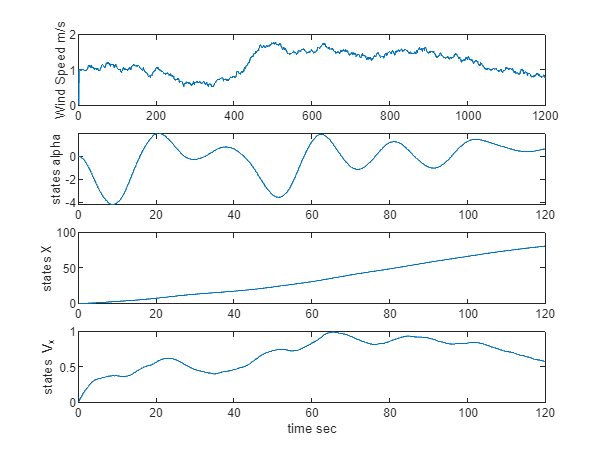

subplot(4,1,1)
plot(w)
ylabel("Wind Speed m/s")
subplot(4,1,2)
plot(t1,rad2deg(Xplant(4,:)))
ylabel("states alpha")
subplot(4,1,3)
plot(t1,Xplant(1,:))
ylabel("states X")
subplot(4,1,4)
plot(t1,Xplant(9,:))
ylabel("states V_x")
xlabel("time sec")

save('Ploting/LinearData_wind.mat', "y");

exportgraphics(gcf,'WindNoControl.pdf','ContentType','vector')